data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;

% 2.1 
eye(2);
G1 = FWT(1:2,1:2);
s = tf('s');
G = G1.C*inv((s*eye(5)-G1.A))*G1.B;
omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
    end
RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



% 2.5 
G=tf(FWT(1:2,1:2));

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])

Wp11 =
 
  0.3333 s + 1.885
  ----------------
   s + 0.0001885
 
Continuous-time transfer function.



Wp=[Wp11 0; 0 wB2] %

Wp =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.




% Control weights
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




Plant=augw(G,Wp,Wu,[]) % build plant
P=minreal(Plant) % to check number of states

P =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  1
 
   z (m):  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
   3:  0
 
   4:  0
 
   Omega (rad/s):  0
 
   z (m):  1
 
  From input "Beta (deg)" to output...
        0.02663 s^5 + 0.1517 s^4 + 0.2955 s^3 + 1.633 s^2 - 0.0007121 s + 0.06518
   1:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
             0.009748 s^3 + 0.006961 s^2 + 0.01499 s + 0.0104
   2:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   3:  0.01
 
   4:  0
 
                   0.07988 s^4 + 0.003315 s^3 + 0.8677 s^2 - 0.006493 s + 0.03458
   Omega (rad/s):  --------------------------------------------------------------
                    s^5 + 0.5979 

% 2.7

[K2,CL2,GAM2,INFO2] = hinfsyn(P,2,2)

K2 =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1   -0.0001885  -1.695e-14  -1.206e-14  -5.084e-14  -2.631e-13  -9.622e-15  -5.425e-12  -4.583e-15
   x2   -1.006e+04       -72.9      -52.63      -217.7       -1080      -42.62  -2.226e+04      -19.48
   x3   -3.297e-13           4  -1.623e-15  -6.839e-15   -3.54e-14  -1.294e-15  -7.298e-13  -6.166e-16
   x4   -2.987e-13  -2.066e-15           1  -6.197e-15  -3.207e-14  -1.173e-15  -6.612e-13  -5.587e-16
   x5   -7.183e-13  -4.968e-15  -3.536e-15         0.5  -7.711e-14   -2.82e-15   -1.59e-12  -1.343e-15
   x6    6.024e-13   4.166e-15   2.965e-15   1.249e-14        0.25   2.365e-15   1.333e-12   1.126e-15
   x7    2.096e-13    1.45e-15   1.032e-15   4.348e-15    2.25e-14    0.007813    4.64e-13    3.92e-16
   x8        -3133      -22.38      -15.46      -67.48      -335.7       -12.3       -6934      -6.693
   x9    1.228e-11   8.496e-14   6.047e-14   2.548e-13   1.

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [30×30 double]
        Y: [30×30 double]
       Ku: [2×30 double]
       Kw: [2×30 double]
       Lx: [30×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]



%Nyquist plot
LoopT=G*K2+eye(2);

LoopT =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1      -0.5979      -2.744      -1.177      -0.271     -0.3654           0           0           0
   x2            4           0           0           0           0           0           0           0
   x3            0           1           0           0           0           0           0           0
   x4            0           0         0.5           0           0           0           0           0
   x5            0           0           0        0.25           0           0           0           0
   x6            0           0           0           0           0     -0.5979      -2.744      -1.177
   x7            0           0           0           0           0           4           0           0
   x8            0           0           0           0           0           0           1           0
   x9            0           0           0           0  

PolesL=pole(minreal(LoopT));

32 states removed.


PolesL =  -57.2562 + 0.0000i
   0.0221 + 3.5415i
   0.0221 - 3.5415i
  -0.0597 + 0.2136i
  -0.0597 - 0.2136i
  -0.0557 + 0.0631i
  -0.0557 - 0.0631i
  -0.0002 + 0.0000i


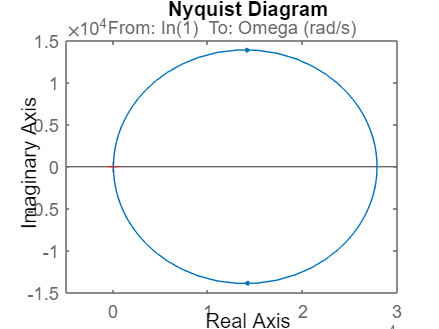

nyqDet=LoopT(1,1)*LoopT(2,2)-LoopT(1,2)*LoopT(2,1);
nyquist(nyqDet)

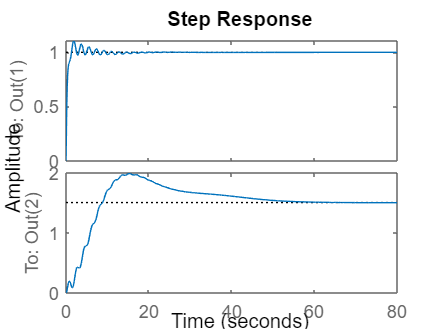

% 2.8 

% Calculate S and T
Sens=(1/Wp)*CL2(1:2,1:2);
Compl=eye(2)-Sens;

% Step in reference
step(Compl(1:2,1))

stepinfo(Compl(1:2,1))

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


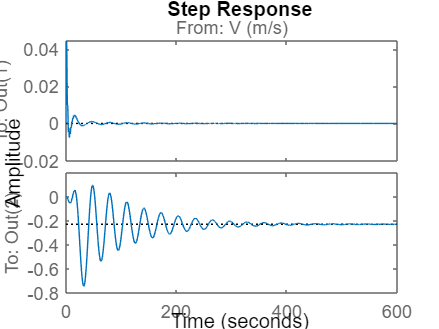



% Plot influence of step in disturbance
D_rej=Sens*FWT(1:2,3);
step(D_rej)

stepinfo(D_rej)

ans = 2×1 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime
